clear all
%Multivariable_Linear_Regression    
% X: independent variables matrix
train=readtable("train.csv");
Y=train.total_fare(1:1500);
%input variables
X=[train.miscellaneous_fees(1:1500),train.fare(1:1500)];%,train.tip(1:100),train.miscellaneous_fees(1:100)];
%defining theta
X=normalize(X);
theta=ones(2,1);
b=1;
N=100;
iterations=500;
cost=zeros(iterations,1);
a=0.1;  
cost_lst = zeros(1,iterations);
m = size(X,1);
for i =1:iterations
       
    H = X*theta+b;
    gradients = (2/m)*(X'*(H-Y));
    theta = theta - a *gradients;
    b=b-a*sum(H-Y)/m;
    cost_value = 1/(2*m)*((H - Y).^2); 
    %Calculate the loss for each training instance
    total = 0;
    for j =1:m
        total = total+ cost_value(j,1);
    end
    %Calculate the cost function for each iteration
    cost_lst(i)=total;
end

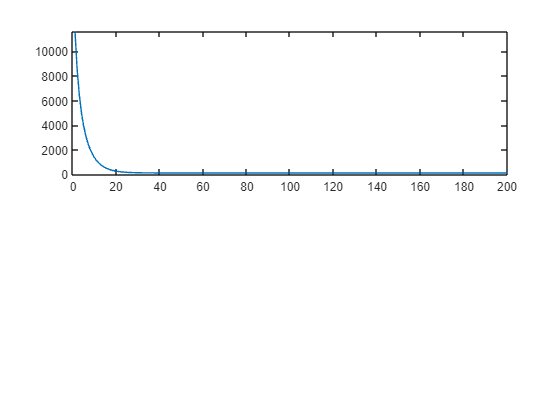


subplot(2,1,1)
plot(1:200,cost_lst(1:200))

disp('Theta:')

Theta:


disp(theta')

   17.6584   79.3580



disp('b:')

b:


disp(b')

  126.1048



% subplot(2,1,2)
% plot(X(:,1),H,'x', X(:,2),H,'-')
% hold on 
% scatter(X(:,1),H,'x','r')
% scatter( X(:,2),H,'o')


% scatter3(X(:,1),X(:,2),Y,'filled')
% hold on
% x1fit = min(X(:,1)):100:max(X(:,1));
% x2fit = min(X(:,2)):100:max(X(:,2));
% [X1FIT,X2FIT] = meshgrid(x1fit,x2fit);
% YFIT =b +  theta(1)*X1FIT + theta(2)*X2FIT;
% surf(X1FIT,X2FIT,YFIT)

% view(50,10)
% hold off



Ytest=train.total_fare(101:151);
display(Ytest')

  Columns 1 through 15

   74.7000  111.0000  162.4500   56.5500   96.0000   69.7500   66.0000   32.2500  139.9500   62.2500   54.7500   58.5000   84.7500   54.7500  262.8750

  Columns 16 through 30

   47.7000  122.3250   69.7500   88.5000  104.1000  120.0000   92.7000   88.2000  142.2000   58.5000  186.0000   73.5000   77.2500  171.4500   92.2500

  Columns 31 through 45

   90.6750  249.7500  534.1500  148.8750  373.8750   79.2000   58.6500   65.7000  189.7500  144.7500   95.5500   43.5000  146.7750  157.8750   79.1250

  Columns 46 through 51

   54.7500   69.7500   62.2500  276.3750  152.3250   90.3750



Xtest=[train.distance_traveled(101:151),train.total_fare(101:151)];
Xtest=normalize(Xtest);
H= (Xtest*theta+b);
disp(H')

  Columns 1 through 15

   79.0718  121.8077  161.1469   58.1781  101.1873   72.0602   71.6202   35.9587  142.3460   66.9485   58.8089   64.1373   88.9232   56.2917  282.4672

  Columns 16 through 30

   52.2353  123.4860   74.5044   97.2794  119.8541  121.9007   98.4829   90.9214  153.7147   64.0278  194.5946   79.4315   87.2041  174.4822   93.4512

  Columns 31 through 45

   94.6461  266.2803  580.2712  152.4046  398.0526   82.7298   62.3367   67.8888  184.8200  151.9243  101.0076   48.3323  141.2783  168.0382   81.8243

  Columns 46 through 51

   58.5900   72.8263   67.7511  307.6322  159.1089   97.0799



accuracy= 1-mean((H-Ytest)./Ytest);
accuracy=accuracy*100

accuracy = 94.1451